mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


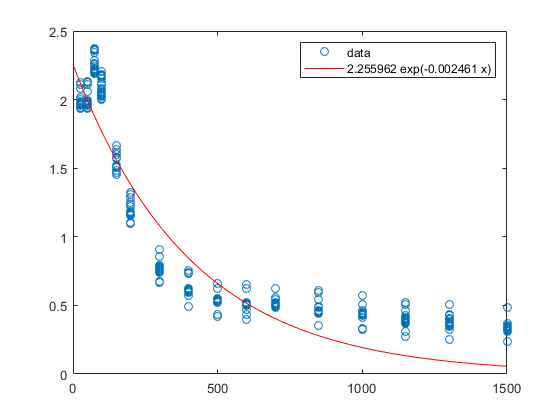

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


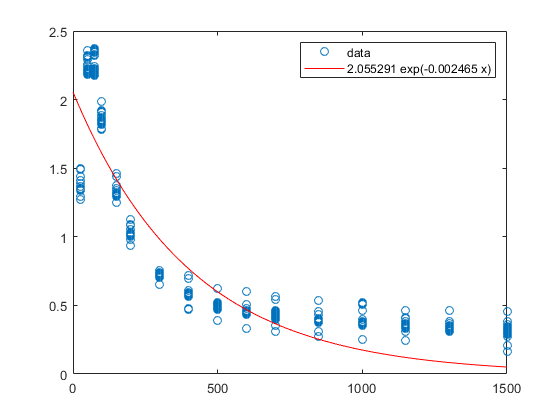

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


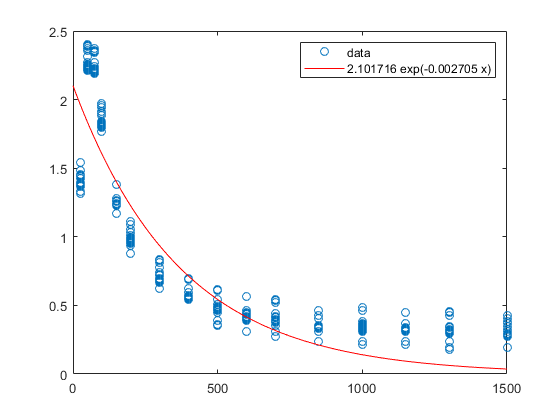

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


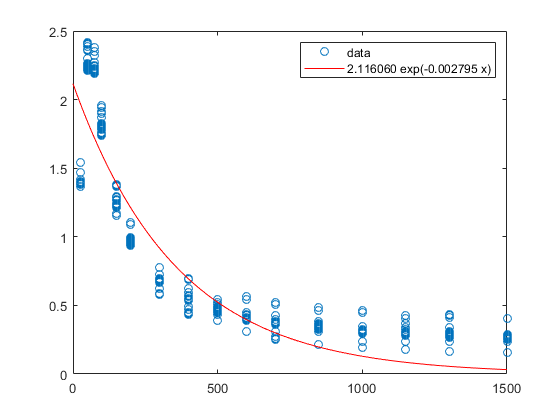

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


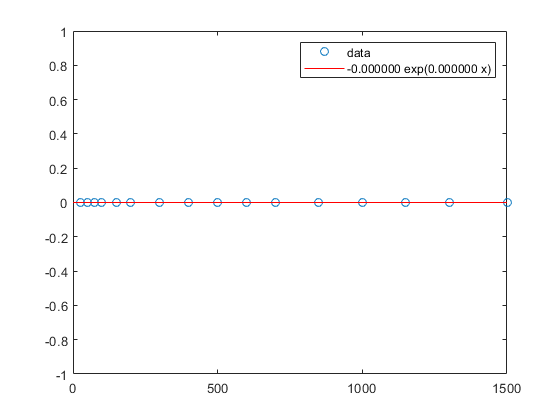

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


load currentState.mat
for i =1:9
    matrix = permute(InfraredSensorArray, [3,1,2]);
    beam1 = matrix(:,:,i);
    beam1rs = reshape(beam1, [1600, 1]);
    distanceArray = [25, 50, 75, 100, 150, 200, 300, 400, 500, 600, 700, 850, 1000, 1150, 1300, 1500];
    xValue = repmat(distanceArray,[100,1]);
    xValuers = reshape(xValue, [1600, 1]);
    
    mask = ~or(isnan(beam1rs), isinf(beam1rs))
    
    
    %scatter(xValuers, beam1rs)

    f0 = fit(xValuers(mask), beam1rs(mask),'exp1');
    
    x = linspace(0,1500,1500);
    figure(i), plot(xValuers(mask), beam1rs(mask), 'o', x, f0(x), '-r'),legend('data',sprintf("%f exp(%f x)", f0.a,f0.b));
    saveas(gcf, sprintf("Figures/Regression IR%d0.png", i));
end

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


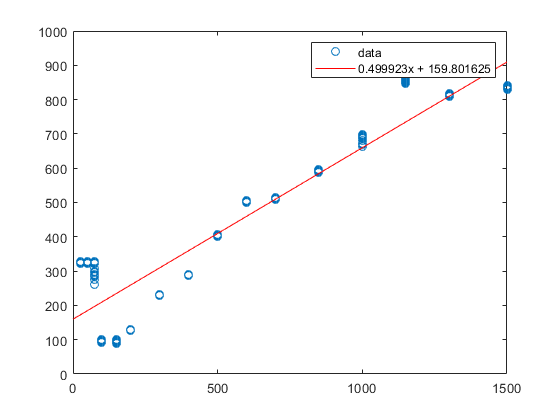

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


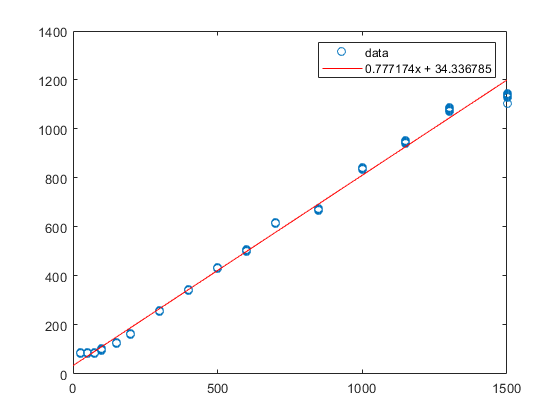

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


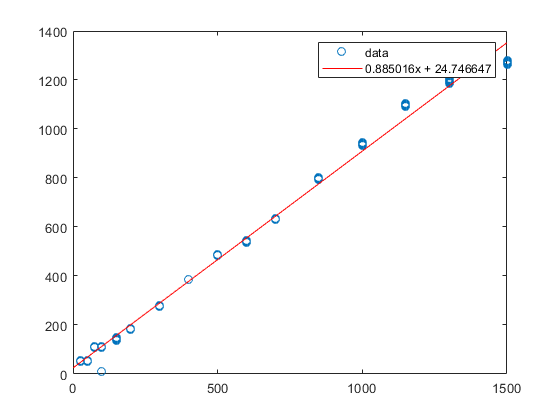

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


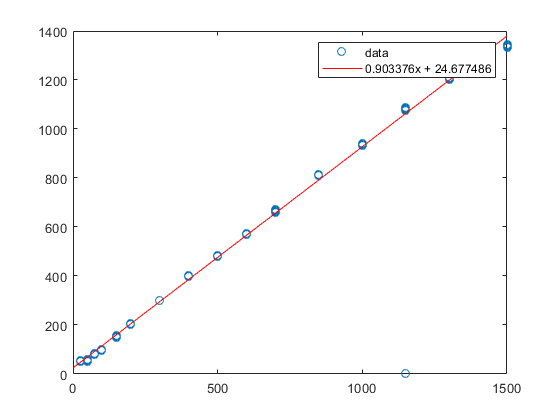

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


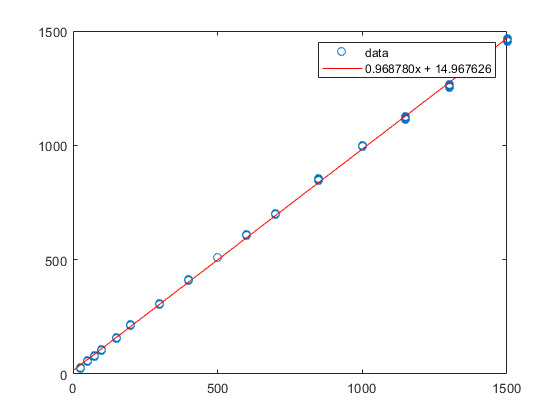

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


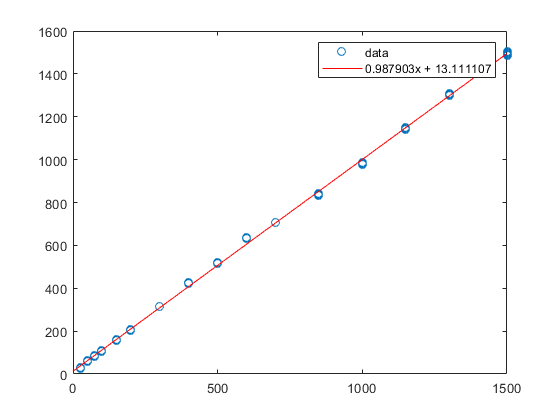

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


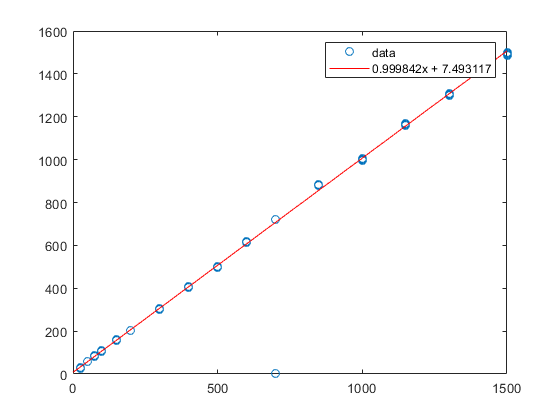

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


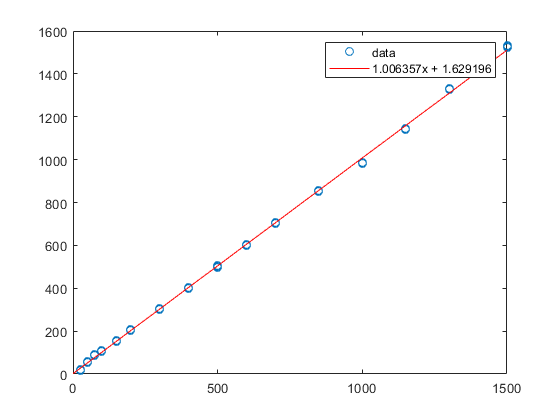

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


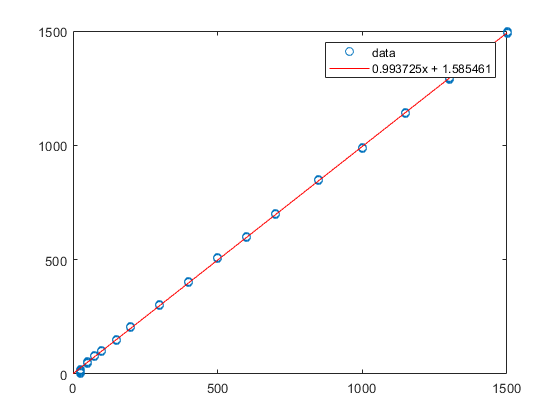


for i =1:9
    matrix = permute(LaserSensorArray, [3,1,2]);
    beam1 = matrix(:,:,i);
    beam1rs = reshape(beam1, [1600, 1]);
    distanceArray = [25, 50, 75, 100, 150, 200, 300, 400, 500, 600, 700, 850, 1000, 1150, 1300, 1500];
    xValue = repmat(distanceArray,[100,1]);
    xValuers = reshape(xValue, [1600, 1]);
    
    mask = ~or(isnan(beam1rs), isinf(beam1rs))
    
    %scatter(xValuers, beam1rs)

    f0 = fit(xValuers(mask), beam1rs(mask),'poly1');

    x = linspace(0,1500,1500);
    figure(i), plot(xValuers(mask), beam1rs(mask), 'o', x, f0(x), '-r'), legend('data',sprintf("%fx + %f", f0.p1,f0.p2));
    saveas(gcf, sprintf("Figures/Regression LA%d0.png", i));

end

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


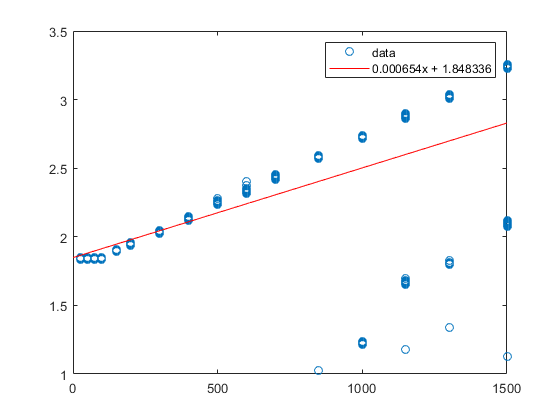

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


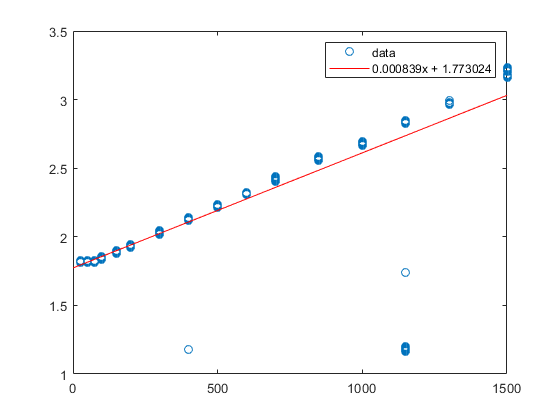

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


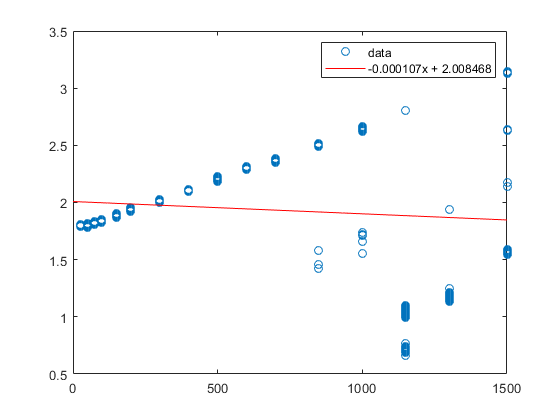

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


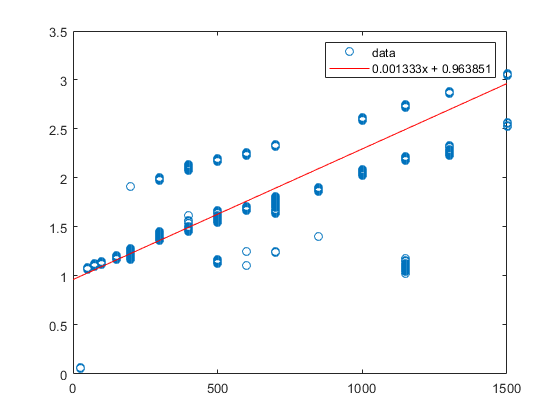

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


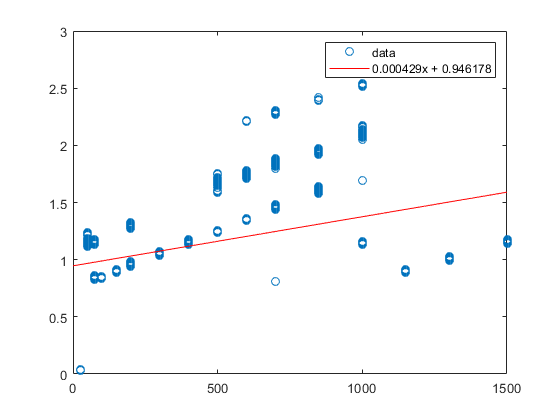

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


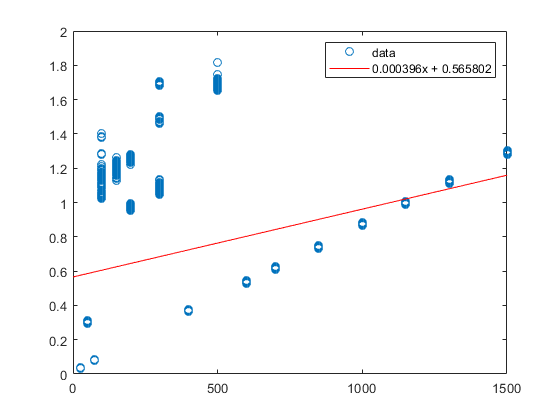

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


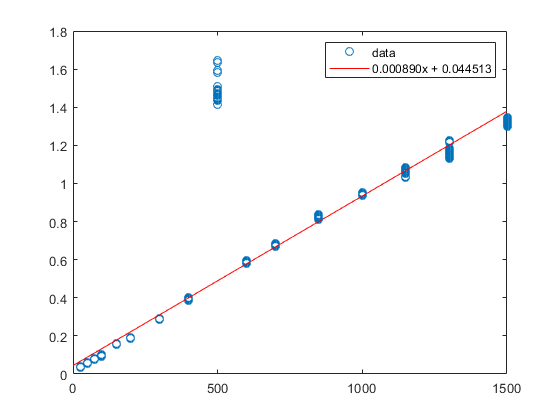

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


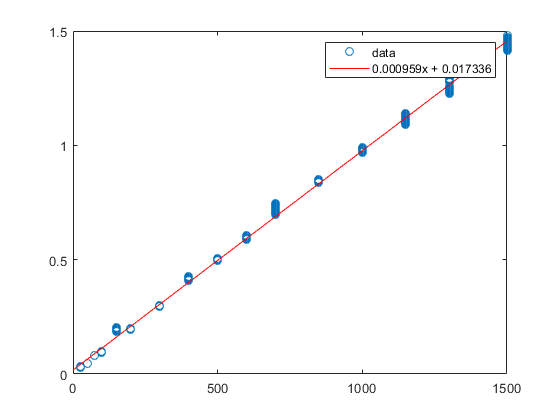

mask = 1600×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


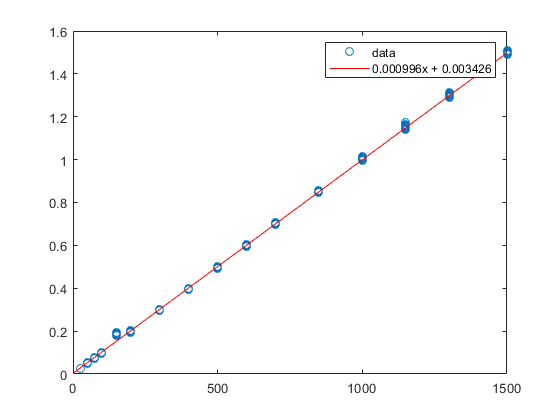

for i =1:9
    matrix = permute(UltrasonicSensorArray, [3,1,2]);
    beam1 = matrix(:,:,i);
    beam1rs = reshape(beam1, [1600, 1]);
    distanceArray = [25, 50, 75, 100, 150, 200, 300, 400, 500, 600, 700, 850, 1000, 1150, 1300, 1500];
    xValue = repmat(distanceArray,[100,1]);
    xValuers = reshape(xValue, [1600, 1]);
    
    mask = ~or(isnan(beam1rs), isinf(beam1rs))
    
    %scatter(xValuers, beam1rs)

    f0 = fit(xValuers(mask), beam1rs(mask),'poly1');

    x = linspace(0,1500,1500);
    figure(i), plot(xValuers(mask), beam1rs(mask), 'o', x, f0(x), '-r'), legend('data',sprintf("%fx + %f", f0.p1,f0.p2));
    saveas(gcf, sprintf("Figures/Regression US%d0.png", i));

end